# Taylor Model

In CORA, Taylor models are instantiated by 

% tay = taylm(I,max_order,name);

where `I` is the interval domain, `max_order` is the maximum polynomial order and `name` is the name of the variable.

Example:

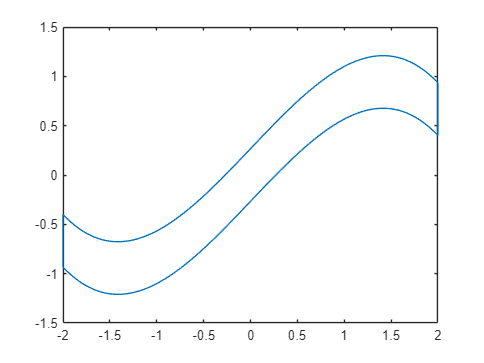

% initialize Taylor model
tx = taylm(interval(-2,2),4,'x');
tay = [tx; sin(tx)];

% plot Taylor model
plot(tay);

For more information, type

help taylm

  taylm (Taylor model) class.
 
  Syntax:
     obj = taylm(int)
     obj = taylm(int,max_order,names,opt_method,eps,tolerance)
     obj = taylm(func,int)
     obj = taylm(func,int,max_order,opt_method,eps,tolerance)
 
  Inputs:
     int - interval object that defines the ranges of the variables
     max_order - the maximal order of a polynomial stored in a polynomial part
     names - cell-array containing the names of the symbolic variables as
             characters (same size as interval matrix 'int')
     func - symbolic function 
     opt_method - method used to calculate interval over-approximations of
                  taylor models 
                   'int': standard interval arithmetic (default)
                   'bnb': branch and bound method is used to find min/max
                   'bnbAdv': branch and bound with re-expansion of taylor models
                   'linQuad': optimization with Linear Dominated Bounder (LDB)
                              and Quadratic Fast Bou